% read in bag-of-word
[M,y] = readdata();

Class 1: 71 items
Class 2: 68 items
M is 139-by-18446, fraction of nonzero entries: 2.078710e-02


[n,m] = size(M);

% run 100 iterations of CUR
% for all parameters
curs = zeros(8,10);
for a = 1:8
    for k = 2:10
        c = a*k; 
        cur_fros = zeros(100,1);
        for iter = 1:100
            [C,U,R] = CUR(M,c,k);
            cur_fros(iter) = norm(M-C*U*R','fro');
        end
        curs(a,k) = mean(cur_fros);
    end
end

% compute truncated svd
[U_,S_,V] = svd(M);
ks = zeros(10,1);
for k = 2:10
    S = S_;
    S(k+1:end,k+1:end) = 0;
    ks(k) = norm(M-U_*S*V','fro');
end

curs

curs = 	1.0e+03 *

         0    1.6568    1.4863    1.4690    1.3979    1.3669    1.3025    1.2247    1.1556    1.1087
         0    1.3877    1.2875    1.2208    1.1670    1.1257    1.0234    0.9792    0.9523    0.9146
         0    1.3072    1.2286    1.1651    1.1060    1.0441    0.9643    0.9320    0.8977    0.8690
         0    1.2744    1.1973    1.1202    1.0482    0.9991    0.9397    0.9018    0.8739    0.8429
         0    1.2350    1.1768    1.0994    1.0165    0.9678    0.9175    0.8821    0.8560    0.8221
         0    1.2192    1.1584    1.0794    0.9869    0.9506    0.9018    0.8704    0.8324    0.8053
         0    1.2000    1.1499    1.0663    0.9554    0.9347    0.8821    0.8462    0.8198    0.7797
         0    1.1891    1.1327    1.0482    0.9385    0.9139    0.8681    0.8298    0.8005    0.7688


ks

ks = 	1.0e+03 *

         0
    1.2602
    1.1741
    1.1029
    1.0428
    0.9843
    0.9411
    0.9014
    0.8701
    0.8401


curs(1,2:end)

ans = 	1.0e+03 *

    1.6568    1.4863    1.4690    1.3979    1.3669    1.3025    1.2247    1.1556    1.1087


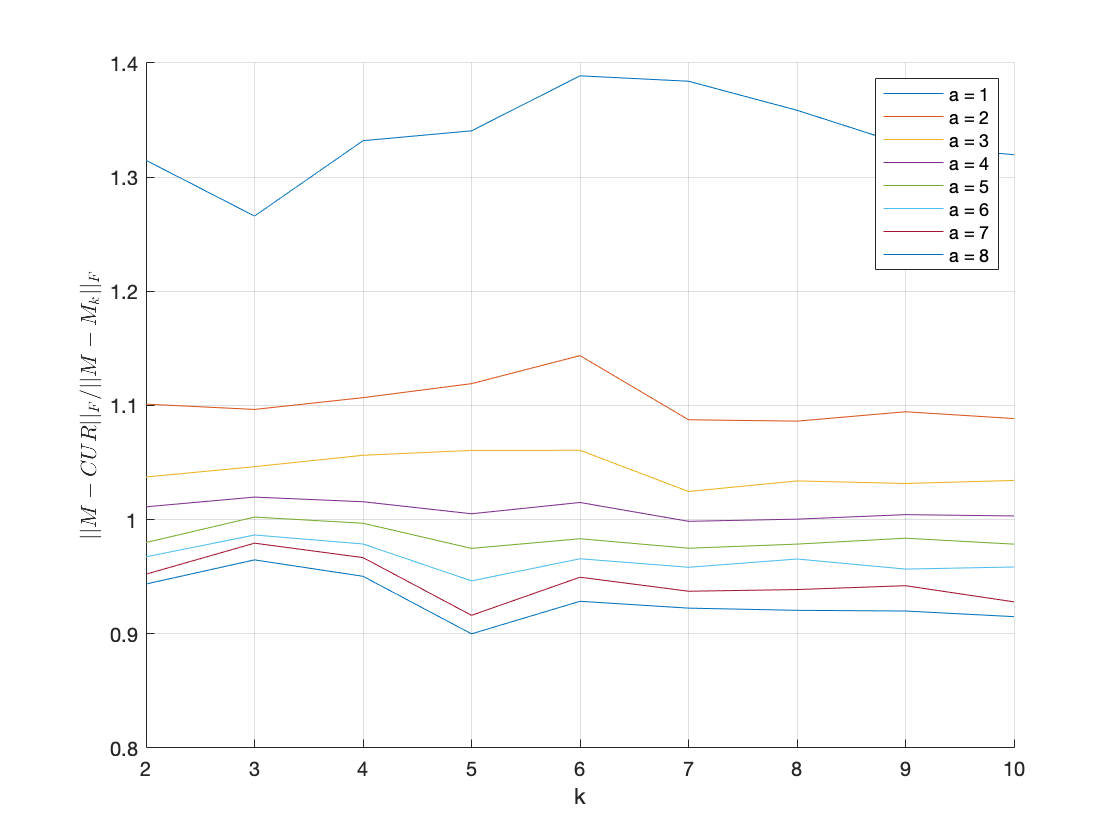

% for each a plot cur/svd_k ratio
close all;
figure;grid;
for a  = 1:8
    hold on; 
    plot(2:10, curs(a,2:end)./ks(2:end)','DisplayName',['a = ' num2str(a)]);
    xlim([2 10]);
    xlabel('k');
    ylabel('$$||M-CUR||_F/||M-M_k||_F$$','interpreter','latex');  
end
legend
saveas(gcf,'figures/cur_ratio.png');

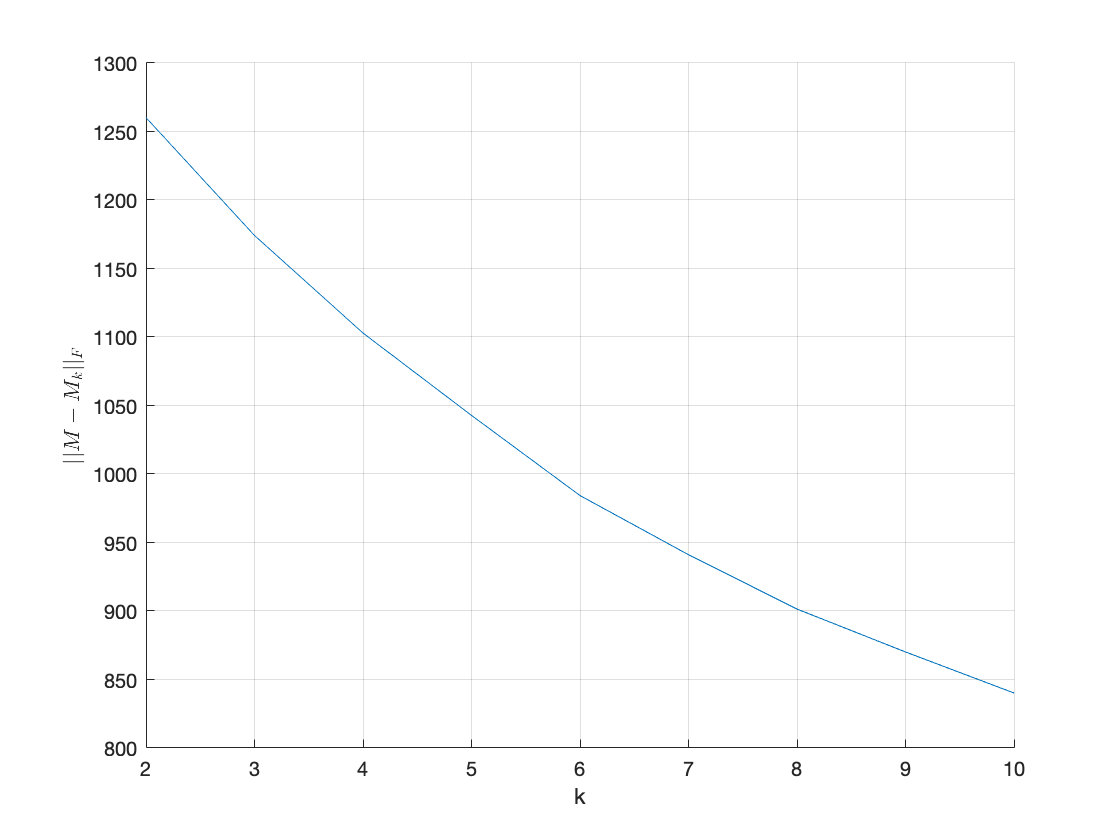

% plot ||M-M_k||_F v.s. k
close all;
figure; grid;
hold on;
plot(2:10, ks(2:end)');
xlabel('k');
ylabel('$$||M-M_k||_F$$','interpreter','latex');
saveas(gcf,'figures/cur_k.png');

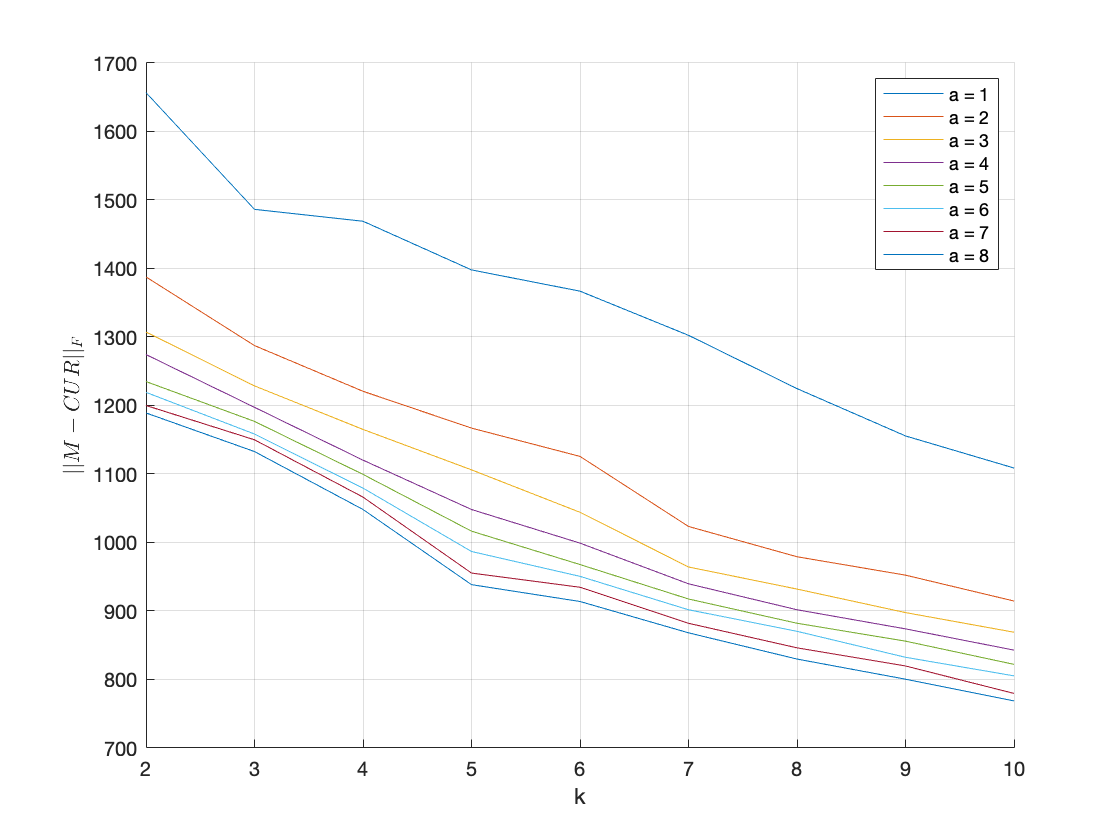

% plot ||M-CUR||_F v.s. k for each a
close all;
figure;grid;
for a  = 1:8
    hold on; 
    plot(2:10, curs(a,2:end)','DisplayName',['a = ' num2str(a)]);
    xlim([2 10]);
    xlabel('k');
    ylabel('$$||M-CUR||_F$$','interpreter','latex');  
end
legend
saveas(gcf,'figures/cur_cur.png');